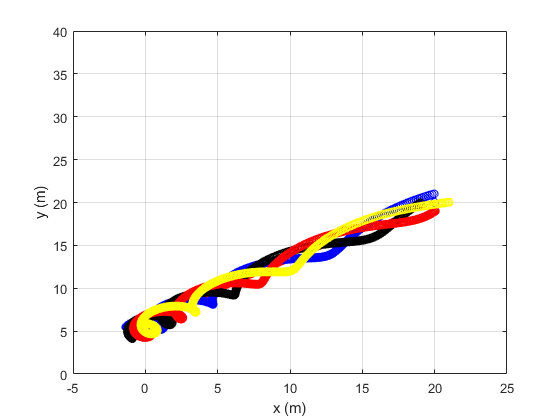

clear
close all
hold off

%Vamos a representar cómo se mueve el centro de la formación

N=4; %Número de robots
iteration=500; %Número de iteraciones
step_size=0.1;
D=1; %Radio de la formación
S=10^-4*[2,1;1,1]; %Matriz
c0=[20;20]; %Posición del centro inicial (initial guess)
r0=[0 0]'; %Centro de contaminación
e=[1;0];
w0=1; %Movimiento circular de un radián por segundo

colors=["ob","ok","or","oy","og"];
tf=20;
t=linspace(0,tf,iteration);
%Condiciones iniciales
c(:,1)=c0;
plot(c0(1,1),c0(2,1),'ob')
hold on
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
mod_rc=mod_r_c(1);
pos_rob=zeros(2,N,iteration);
i=1;

while mod_rc>0.001
    grad_sum=0;
    i=i+1;
    if i==500
        break
    end
    
    for j=1:N
        %A este ángulo se le puede añadir movimiento rotatorio (w*t)
        phi=w0*t(i)+2*pi()*j/N;
        R=[cos(phi) -sin(phi);sin(phi) cos(phi)];
        %Posición del robot individual
        pos_rob(:,j,i)=c0+D*R*e;
        r_i=pos_rob(:,j,i);
        %Suma para el gradiente (esto luego se utiliza para la aprox. del
        %grad. en el centro)
        grad_sum=grad_sum+100*exp(-r_i'*S*r_i)*(r_i-c0);
    end
        %Aproximación del gradiente en el centro
    grad_centr=2/(N*D^2)*grad_sum;
    grad_exacto=calcular_gradiente2D(c0);
    error_gradiente(i)=norm(grad_centr-grad_exacto);
    L(i)=error_gradiente(i)/D;
        %Aplicación del método del gradiente ascendente
    c(:,i)=c0+step_size*grad_centr;
        %Hay un nuevo centro alrededor del cual se tienen que poner los robots
    c0=c(:,i);
        %Sacar el módulo de la diferencia entre el centro y el punto de
        %contaminación para cada iteración
    mod_r_c(i)=norm(c0-r0);
    mod_rc=mod_r_c(i);
end

%Representación del centro
plot(c(1,:),c(2,:),'.r')
xlabel("x (m)")
ylabel("y (m)")
grid on
%Representación de los robots
for g=1:N
    for z=2:length(mod_r_c)
        plot(pos_rob(1,g,z),pos_rob(2,g,z),colors(g))
        hold on
    end
end
axis([-5 25 0 40])
hold off

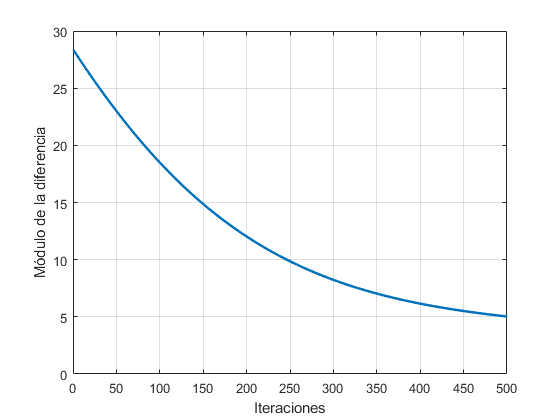

plot(1:length(mod_r_c),mod_r_c,".")
xlabel("Iteraciones")
ylabel("Módulo de la diferencia")
axis([0 500 0 30])
grid on

%error final para cada step-size
error=norm(c(:,length(mod_r_c))-r0)

error = 5.0393

c0

c0 =    -0.4619
    5.0181


L_max=max(L)

L_max = 2.6303e-04